# NR FDD Scheduling Performance Evaluation

This example demonstrates how to configure a scheduling strategy and measure its performance in frequency division duplexing (FDD) mode. It evaluates the performance of the round-robin (RR) scheduling strategy in terms of achieved throughput and fairness in resource sharing. Additionally, you can utilize the proportional fair (PF) and best channel quality indicator (Best CQI) scheduling strategies. Furthermore, this example illustrates how to establish multiple logical channels between a user equipment (UE) node and a 5G base station (gNB) node.

## Introduction

To assign DL and UL resources, this example uses an RR scheduler. The scheduler allocates resources based on pending retransmissions, buffer status, and channel quality for the UE nodes.

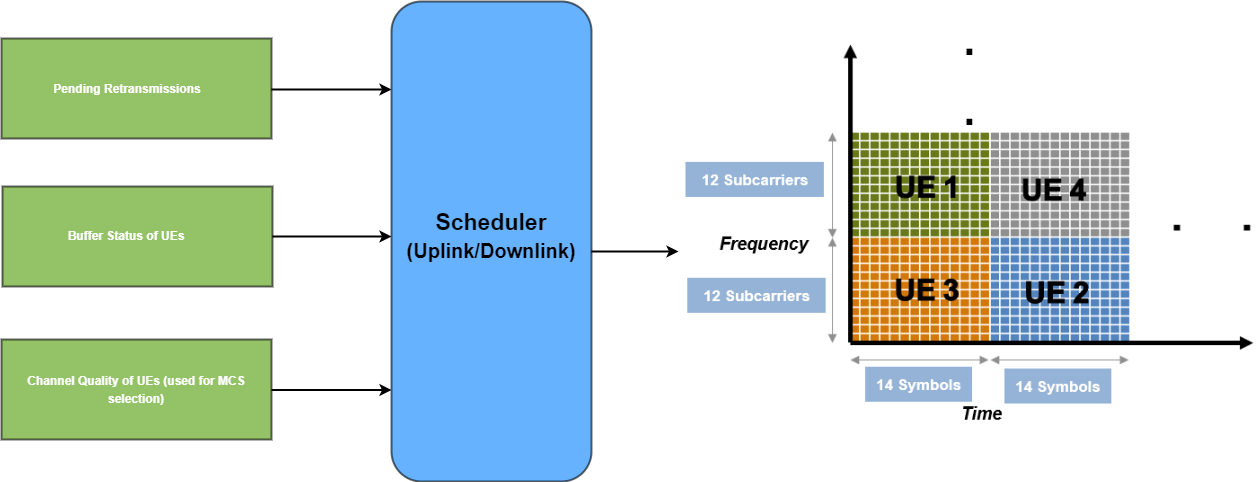

This example models:

- Slot-based DL and UL scheduling.

- Multiple logical channels (LCHs) to support different kind of applications.

- Logical channel prioritization (LCP) to distribute the received assignment among logical channels per UE node for UL and DL.

- Link-to-system mapping-based abstracted physical layer (PHY).

- 3GPP TR 38.901 channel model.

This example assumes that nodes send the control packets out of band, eliminating the requirement for transmission resources and ensuring error-free reception.The control packets are UL assignment, DL assignment, buffer status report (BSR), and PDSCH feedback.

## Scenario simulation

Check if the Communications Toolbox Wireless Network Simulation Library support package is installed. If the support package is not installed, MATLAB® returns an error with a link to download and install the support package.

wirelessnetworkSupportPackageCheck

Create a wireless network simulator.

rng("default")                             % Reset the random number generator
numFrameSimulation = 100; % Simulation time in terms of number of 10 ms frames
networkSimulator = wirelessNetworkSimulator.init;

Create a gNB node by specifying its position, duplex mode, carrier frequency, channel bandwidth, subcarrier spacing, and receive gain. Set the sounding reference signal (SRS) transmission periodicity to 5 slots for all UEs connecting to this gNB.

gNB = nrGNB(Position=[0 0 30],DuplexMode="FDD",CarrierFrequency=2.6e9,ChannelBandwidth=30e6,SubcarrierSpacing=15e3,ReceiveGain=11,SRSPeriodicityUE=5);

To set the scheduler parameters `Scheduler` and `ResourceAllocationType`, use the `configureScheduler` function. Set the value of `Scheduler` parameter to `RoundRobin` and `ResourceAllocationType` to 0. You can also set the value of `Scheduler` to `ProportionalFair` or `BestCQI` and `ResourceAllocationType` to 1.

configureScheduler(gNB,Scheduler="RoundRobin",ResourceAllocationType=0);

Create 4 UE nodes. Specify the name, the position, and the receive gain of each UE node.

uePositions = [100 0 3; 250 0 3; 700 0 3; 750 0 3];
ueNames = "UE-" + (1:size(uePositions,1));
UEs = nrUE(Name=ueNames,Position=uePositions,ReceiveGain=11);

Load the application configuration table into the `AppConfig` parameter, containing these fields. Each row in the table represents one application and has these properties as columns.

- DataRate - Application traffic generation rate (in kilobits per second).

- PacketSize - Size of the packet (in bytes).

- HostDevice - Specify the device (UE or gNB) that has an application with the specified configuration installed on it. The device takes values 0 or 1. The values 0 and 1 indicate the configuration of application is at the gNB and the UE, respectively.

- RNTI - Radio network temporary identifier of a UE node. This identifies the UE node for which the application is installed.

- LogicalChannelID - Logical channel identifier.

- BearerType - Specify the RLC bearer type for the selected logical channel identifier. The values can be either 0 or 1, where 0 indicates the RLC unacknowledged mode (UM) bearer and 1 indicates the RLC acknowledged mode (AM) bearer.

load("NRFDDAppConfig.mat")
% Validate the host device type for the applications configured
validateattributes(AppConfig.HostDevice,{'numeric'},{"nonempty","integer",">=",0,"<=",1},"AppConfig.HostDevice", ...
    "HostDevice");

Load the RLC bearer configuration table into the `RLCChannelConfig` parameter. Each row in the table represents one RLC bearer and has these properties as columns.

- RNTI - Radio network temporary identifier of the UE.

- LogicalChannelID - Logical channel identifier.

- LogicalChannelGroup - Logical channel group identifier.

- RLCEntityType - RLC entity type. The possible values are "UMDL" for unidirectional DL RLC UM bearer, "UMUL" for unidirectional UL RLC UM bearer, "UM" for bidirectional RLC UM bearer, and "AM" for RLC AM bearer.

- Priority - Priority of the logical channel.

- SNFieldLength - Sequence number field length. If the RLCEntityType is "UM", "UMUL", or "UM", it takes either 6 or 12. On the other hand, if the RLCEntityType is "AM", it takes either 12 or 18.

- BufferSize - Maximum transmitter buffer size in terms of number of higher layer service data units (SDUs).

- PollPDU - Allowable number of acknowledged mode data (AMD) protocol data unit (PDU) transmissions before requesting the status PDU. This property is only applicable for the RLC AM entity.

- PollByte - Allowable number of service data unit (SDU) byte transmissions before requesting the status PDU. This property is only applicable for the RLC AM entity.

- PollRetransmitTimer - Waiting time (in milliseconds) before retransmitting the status PDU request. This is only applicable for RLC AM entity.

- MaxRetxThreshold - Maximum number of retransmissions of an AMD PDU. This property is only applicable for the RLC AM entity.

- ReassemblyTimer - Waiting time (in milliseconds) before declaring the reassembly failure of SDUs in the reception buffer.

- StatusProhibitTimer - Waiting time (in milliseconds) before transmitting the status PDU following the previous status PDU transmission. This is only applicable for RLC AM entity.

- PrioritizedBitRate - Prioritized bit rate (in kilobytes per second) of the logical channel.

- BucketSizeDuration - Bucket size duration (in milliseconds) of the logical channel.

load("NRFDDRLCChannelConfig.mat")

To add RLC AM bearers between the gNB and UE nodes, set `enableRLCAMBearers` to `true`. Setting the `enableRLCAMBearers` parameter to `false` does not create RLC AM bearers and their associated traffic objects.

enableRLCAMBearers = false;

Create a set of RLC bearer configuration objects.

rlcBearers = cell(1, numel(UEs));
rlcBearersInfo = table2struct(RLCChannelConfig(1:end, 2:end));
for rlcBearerInfoIdx = 1:size(RLCChannelConfig, 1)
    rlcBearerConfigStruct = rlcBearersInfo(rlcBearerInfoIdx);
    ueIdx = RLCChannelConfig.RNTI(rlcBearerInfoIdx);
    % Check if the RLC AM bearer configuration is in disabled mode
    if rlcBearerConfigStruct.RLCEntityType == "AM" && ~enableRLCAMBearers
        continue;
    end

    % Create an RLC bearer configuration object with the specified RLC bearer
    % configuration
    rlcBearerObj = nrRLCBearerConfig(LogicalChannelID=rlcBearerConfigStruct.LogicalChannelID, ...
        RLCEntityType=rlcBearerConfigStruct.RLCEntityType, ...
        SNFieldLength=rlcBearerConfigStruct.SNFieldLength, ...
        BufferSize=rlcBearerConfigStruct.BufferSize, PollPDU=rlcBearerConfigStruct.PollPDU, ...
        PollByte=rlcBearerConfigStruct.PollByte, ...
        PollRetransmitTimer=rlcBearerConfigStruct.PollRetransmitTimer, ...
        MaxRetxThreshold= rlcBearerConfigStruct.MaxRetxThreshold, ...
        ReassemblyTimer=rlcBearerConfigStruct.ReassemblyTimer, ...
        StatusProhibitTimer=rlcBearerConfigStruct.StatusProhibitTimer, ...
        LogicalChannelGroup=rlcBearerConfigStruct.LogicalChannelGroup, ...
        Priority=rlcBearerConfigStruct.Priority, ...
        PrioritizedBitRate=rlcBearerConfigStruct.PrioritizedBitRate, ...
        BucketSizeDuration=rlcBearerConfigStruct.BucketSizeDuration);

    rlcBearers{ueIdx} = [rlcBearers{ueIdx} rlcBearerObj];
end

Connect the UE nodes to the gNB node using the [connectUE](docid:5g_ref#mw_3d64d440-0c91-4e09-b867-b30521e76cf8) object function. Specify the RLC bearer configuration for establishing an RLC bearer between the gNB node and each UE node, set the buffer status report (BSR) periodicity to 5 (in number of subframes), and set the DL channel status information (CSI) report periodicity to 10 (in number of slots). For more information about BSR, see [Communication Between gNB and UE Nodes](docid:5g_ug#mw_f30ce7be-b18d-49a0-8ad1-1594f9c77a60).

for ueIdx = 1:numel(UEs)
    connectUE(gNB,UEs(ueIdx),BSRPeriodicity=5,CSIReportPeriodicity=10,RLCBearerConfig=rlcBearers{ueIdx})
end

Set the periodic DL and UL application traffic pattern for UEs.

for appIdx = 1:size(AppConfig,1)

    % Do not create traffic objects for RLC AM bearers if you have disabled the
    % RLC AM bearer configurtion
    if AppConfig.TrafficForAM(appIdx) && ~enableRLCAMBearers
        continue;
    end
    % Create an object for the On-Off network traffic pattern
    app = networkTrafficOnOff(PacketSize=AppConfig.PacketSize(appIdx),GeneratePacket=true, ...
            OnTime=numFrameSimulation/100,OffTime=0,DataRate=AppConfig.DataRate(appIdx));

    if AppConfig.HostDevice(appIdx) == 0
        % Add traffic pattern that generates traffic on downlink
        addTrafficSource(gNB,app,DestinationNode=UEs(AppConfig.RNTI(appIdx)),LogicalChannelID=AppConfig.LogicalChannelID(appIdx))
    else
        % Add traffic pattern that generates traffic on uplink
        addTrafficSource(UEs(AppConfig.RNTI(appIdx)),app,LogicalChannelID=AppConfig.LogicalChannelID(appIdx))
    end
end

Add the gNB and UE nodes to the network simulator.

addNodes(networkSimulator,gNB)
addNodes(networkSimulator,UEs)

Use 3GPP TR 38.901 channel model for all links. You can also run the example with a free space path loss model.

channelModel = "3GPP TR 38.901";

if strcmp(channelModel,"3GPP TR 38.901")
    % Define scenario boundaries
    pos = reshape([gNB.Position UEs.Position],3,[]);
    minX = min(pos(1,:));          % x-coordinate of the left edge of the scenario in meters
    minY = min(pos(2,:));          % y-coordinate of the bottom edge of the scenario in meters
    width = max(pos(1,:)) - minX;  % Width (right edge of the 2D scenario) in meters, given as maxX - minX
    height = max(pos(2,:)) - minY; % Height (top edge of the 2D scenario) in meters, given as maxY - minY

    % Create the channel model
    channel = h38901Channel(Scenario="UMa",ScenarioExtents=[minX minY width height]);
    % Add the channel model to the simulator
    addChannelModel(networkSimulator,@channel.channelFunction);
    connectNodes(channel,networkSimulator);
end

Set the `enableTraces` to `true` to log the traces. When you set the `enableTraces` parameter to `false`, the simulation does not log any traces. However, setting `enableTraces` to `false` can speed up the simulation.

enableTraces = true;

The `cqiVisualization` and `rbVisualization` parameters control the display of the CQI visualization and the RB assignment visualization, respectively. By default, these plots are in enabled mode. You can disable them by setting the respective flags to false.

cqiVisualization = true;
rbVisualization = true;

Set up the RLC logger and the scheduling logger.

if enableTraces
    % Create an object for RLC traces logging
    simRLCLogger = helperNRRLCLogger(numFrameSimulation,gNB,UEs);
    % Create an object for scheduler traces logging
    simSchedulingLogger = helperNRSchedulingLogger(numFrameSimulation,gNB,UEs);
    % Create an object for CQI and RB grid visualization
    gridVisualizer = helperNRGridVisualizer(numFrameSimulation,gNB,UEs,CQIGridVisualization=cqiVisualization, ...
        ResourceGridVisualization=rbVisualization,SchedulingLogger=simSchedulingLogger);
end

Log the UL and DL MAC packets of the UE node with an RNTI value of 1 into a packet capture (PCAP) file by setting the `enablePCAPLogging` flag to true.

enablePCAPLogging = false; % Enable or disable PCAP logging
if enablePCAPLogging
    ueCapturefileName = "UE_RNTI-"+UEs(1).RNTI+"_Name-"+UEs(1).Name+"_"+second(datetime('now')); % Generate the capture file name using the RNTI and name of the UE
    packetCaptureObj = helperNRMACPacketCapture(UEs(1), ueCapturefileName); % Create a helperNRMACPacketCapture object to log MAC packets
end

Set the number of updates per second for the metric plots.

numMetricPlotUpdates = 20; % Updates plots every 50 milliseconds

Set up metric visualizer.

showSchedulerMetrics = true;
showRLCMetrics = true;
metricsVisualizer = helperNRMetricsVisualizer(gNB,UEs,RefreshRate=numMetricPlotUpdates, ...
    PlotSchedulerMetrics=showSchedulerMetrics,PlotRLCMetrics=showRLCMetrics);

Write the logs to MAT-files. The example uses these logs for post-simulation analysis.

simulationLogFile = "simulationLogs"; % For logging the simulation traces

Run the simulation for the specified `numFrameSimulation` frames.

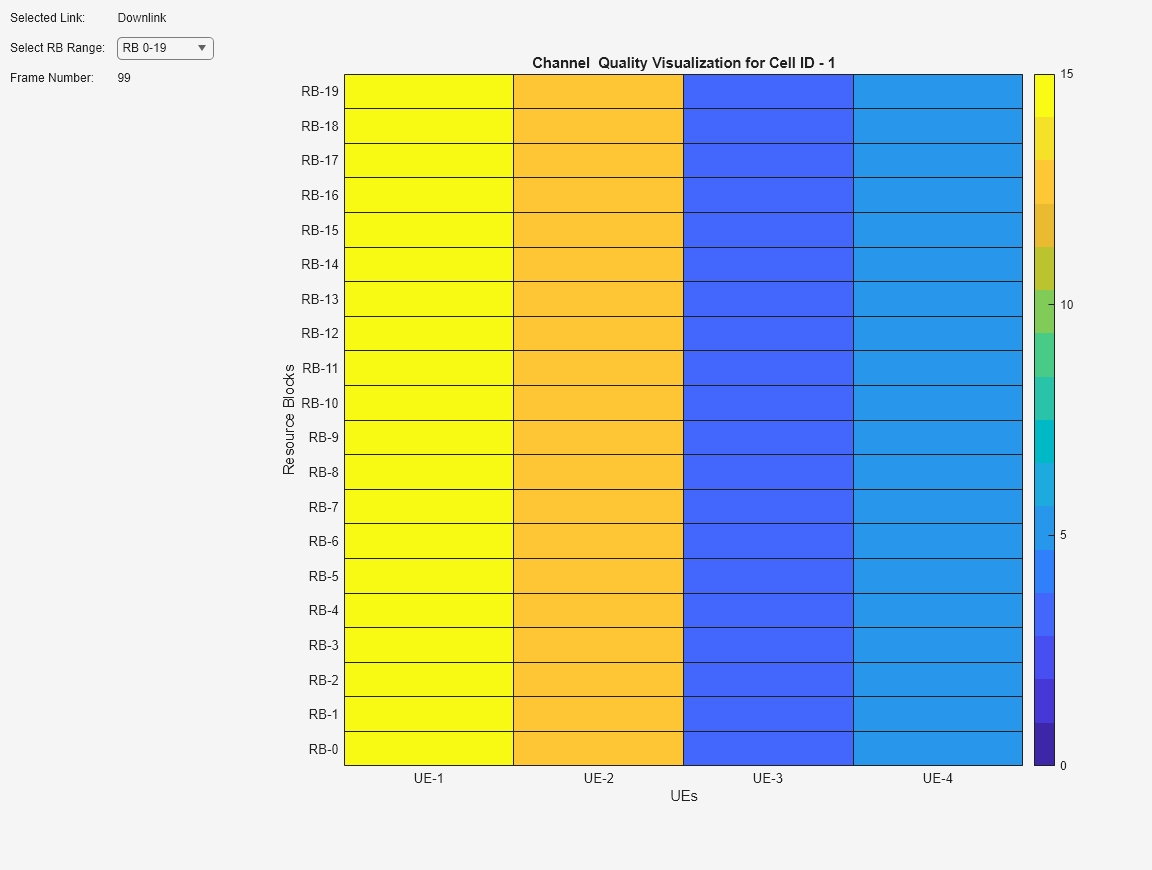

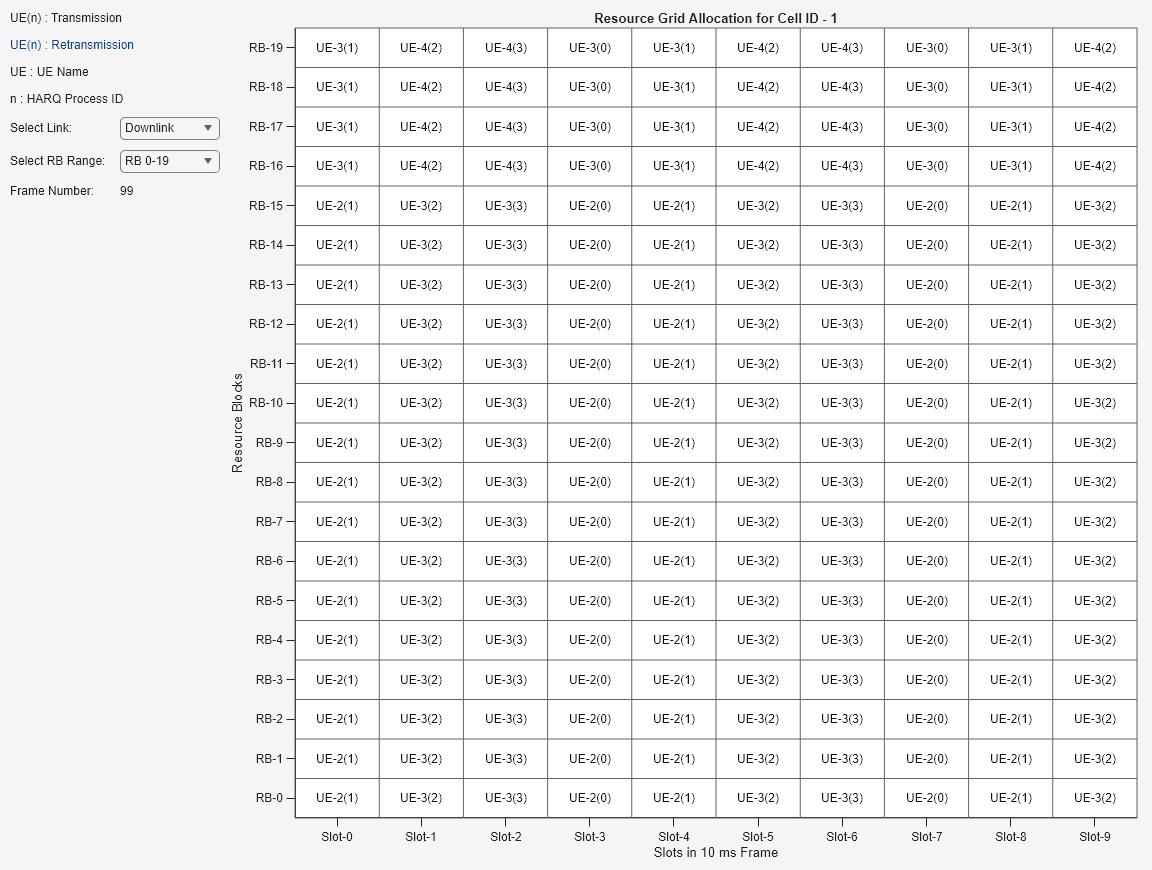

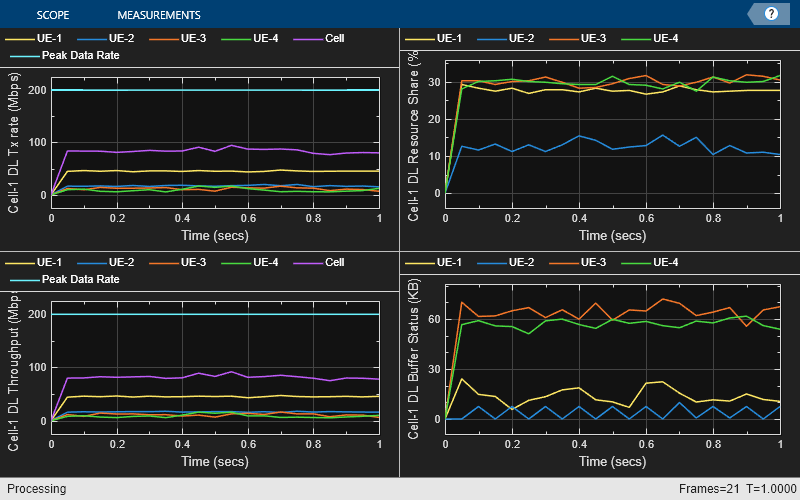

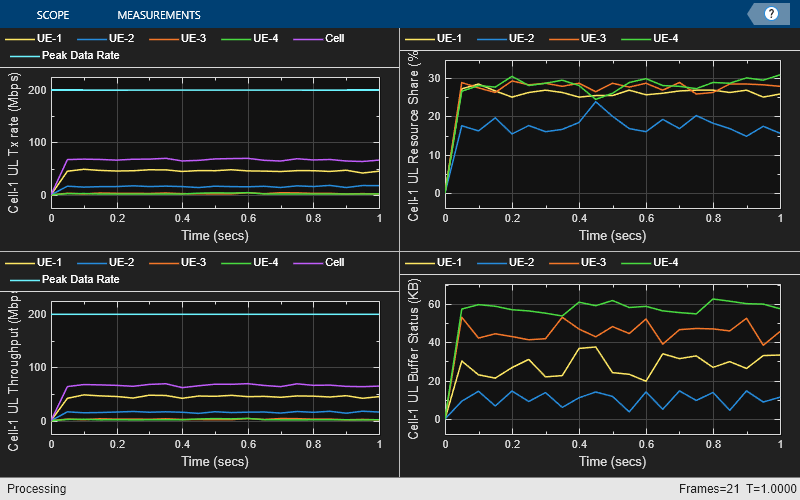

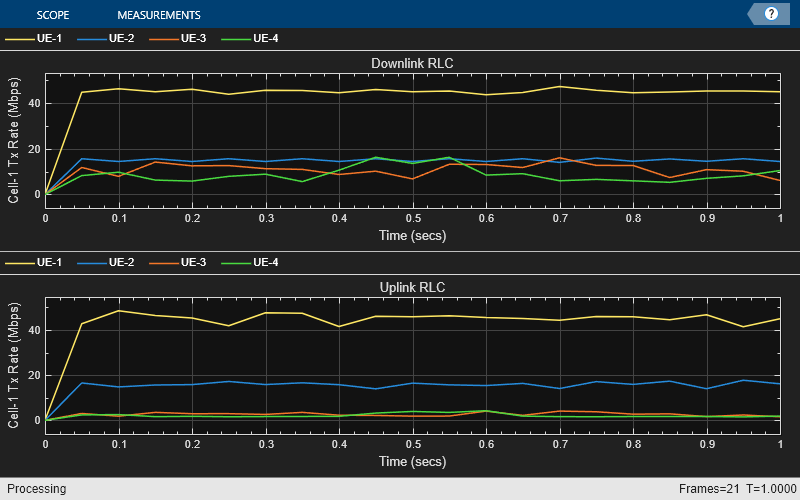

% Calculate the simulation duration (in seconds)
simulationTime = numFrameSimulation*1e-2;
% Run the simulation
run(networkSimulator,simulationTime);

Read per-node statistics.

gNBStats = statistics(gNB, "all");
ueStats = statistics(UEs);

At the end of the simulation, compare the achieved values for system performance indicators with theoretical peak values (considering zero overheads). Performance indicators displayed are achieved data rate (UL and DL), achieved spectral efficiency (UL and DL), and block error rate (BLER) observed for UEs (UL and DL). The calculated peak values are in accordance with 3GPP TR 37.910.

displayPerformanceIndicators(metricsVisualizer)

Peak UL throughput: 199.08 Mbps. Achieved cell UL throughput: 66.14 Mbps
Achieved UL throughput for each UE: [45.25        15.95         2.75         2.19]
Peak UL spectral efficiency: 6.64 bits/s/Hz. Achieved UL spectral efficiency for cell: 2.20 bits/s/Hz 
Block error rate for each UE in the UL direction: [0.011       0.007           0       0.008]

Peak DL throughput: 199.08 Mbps. Achieved cell DL throughput: 81.65 Mbps
Achieved DL throughput for each UE: [45.16        16.56        11.12         8.81]
Peak DL spectral efficiency: 6.64 bits/s/Hz. Achieved DL spectral efficiency for cell: 2.72 bits/s/Hz
Block error rate for each UE in the DL direction: [0       0.046       0.055       0.058]



## Simulation Visualization

To evaluate the performance of the cell, the example includes various runtime visualizations. For further details on the runtime visualizations presented, refer to [Simulation Visualization](docid:5g_ug#mw_73df19f5-3900-4a27-84a4-8d702b76679e).

## Simulation Logs

This example stores the simulation logs in MAT-files for the post-simulation analysis. The MAT-file `simulationLogFile` saves the per time step logs, the scheduling assignment logs, and the RLC logs. After the simulation, open the file to load `DLTimeStepLogs`, `ULTimeStepLogs`, `SchedulingAssignmentLogs`, RLC`Logs` in the workspace.

**Time step logs:** For more information on the time step log format, see the [NR Cell Performance Evaluation with MIMO](docid:5g_ug#mw_5b092ec2-40de-4aff-a2ad-dcef2ffe8654) example.

**Scheduling assignment logs:** For more information on the scheduling log format, see the [NR Cell Performance Evaluation with MIMO](docid:5g_ug#mw_5b092ec2-40de-4aff-a2ad-dcef2ffe8654) example.

**RLC logs: **Each row in the RLC logs represents a slot and contains this information:

- *Timestamp*: Timestamp (in milliseconds)

- *Frame*: Frame number.

- *Slot*: Slot number in the frame.

- *UE RLC statistics*: *N*-by-P cell, where *N* is the number of UE nodes, and *P *is the number of statistics collected.  Each row represents statistics of a UE node. The last row contains the cumulative RLC statistics of the entire simulation.

- *gNB RLC statistics*: *N*-by-P cell, where *N* is the number of UE nodes, and *P *is the number of statistics collected. Each row represents statistics of all logical channel of a UE node at the gNB. The last row contains the cumulative RLC statistics of the entire simulation.

Each row of the UE and gNB RLC statistics table represents a logical channel of a UE and contains:

- *UEID*: Node ID of a UE node.

- *RNTI*: Radio network temporary identifier of a UE node.

- *TransmittedPackets*: Number of packets sent by RLC to MAC layer.

- *TransmittedBytes*: Number of bytes sent by RLC to MAC layer.

- *ReceivedPackets*: Number of packets received by RLC from MAC layer.

- *ReceivedBytes*: Number of bytes received by RLC from MAC layer.

- *DroppedPackets*: Number of received packets from MAC which are dropped by RLC layer.

- *DroppedBytes*: Number of received bytes from MAC which are dropped by RLC layer.

Save the simulation logs in a MAT file.

if enableTraces
    simulationLogs = cell(1,1);
    if gNB.DuplexMode == "FDD"
        logInfo = struct(DLTimeStepLogs=[],ULTimeStepLogs=[],SchedulingAssignmentLogs=[],RLCLogs=[]);
        [logInfo.DLTimeStepLogs,logInfo.ULTimeStepLogs] = getSchedulingLogs(simSchedulingLogger);
    else % TDD
        logInfo = struct(TimeStepLogs=[],SchedulingAssignmentLogs=[],RLCLogs=[]);
        logInfo.TimeStepLogs = getSchedulingLogs(simSchedulingLogger);
    end
         % Obtain the scheduling assignments log
    logInfo.SchedulingAssignmentLogs = getGrantLogs(simSchedulingLogger);
         % Get the RLC logs
    logInfo.RLCLogs = getRLCLogs(simRLCLogger);
         % Save simulation logs in a MAT-file
    simulationLogs{1} = logInfo;
    save(simulationLogFile,"simulationLogs")
end

Close the packet writer object.

if enablePCAPLogging
    close(packetCaptureObj);
end

## Further Exploration

Try running the example with these modifications.

### TDD modeling

Explore TDD modeling by setting the DuplexMode property of the `gNB` object to "TDD". You can also customize the DL-UL slot pattern configuration for TDD by using the DLULConfigTDD property of the nrGNB object.

### Full buffer traffic modeling

Consider using the full buffer traffic model instead of custom traffic models in this example. For more information on the workflow, see the [NRFDDSchedulingPerformanceEvaluationWithFullBuffer.m](matlab:edit('NRFDDSchedulingPerformanceEvaluationWithFullBuffer.m')) script. This script evaluates the effect of scheduling algorithms (RR, PF, and Best CQI) on cell throughput for a simulation duration of 100 frames. The empirical cumulative distribution function (ECDF) plots demonstrate the evaluation results of RR, PF, and Best CQI scheduling algorithms. The Best CQI scheduling algorithm obtains a significant cell throughput gain in the UL and DL directions because it prioritizes the UEs with the best channel quality. The RR scheduling algorithm, on the other hand, obtains poor cell throughput because it prioritizes only fairness in scheduling. You can achieve a compromise between the RR and BestCQI scheduling algorithms when you use the PF scheduling algorithm.

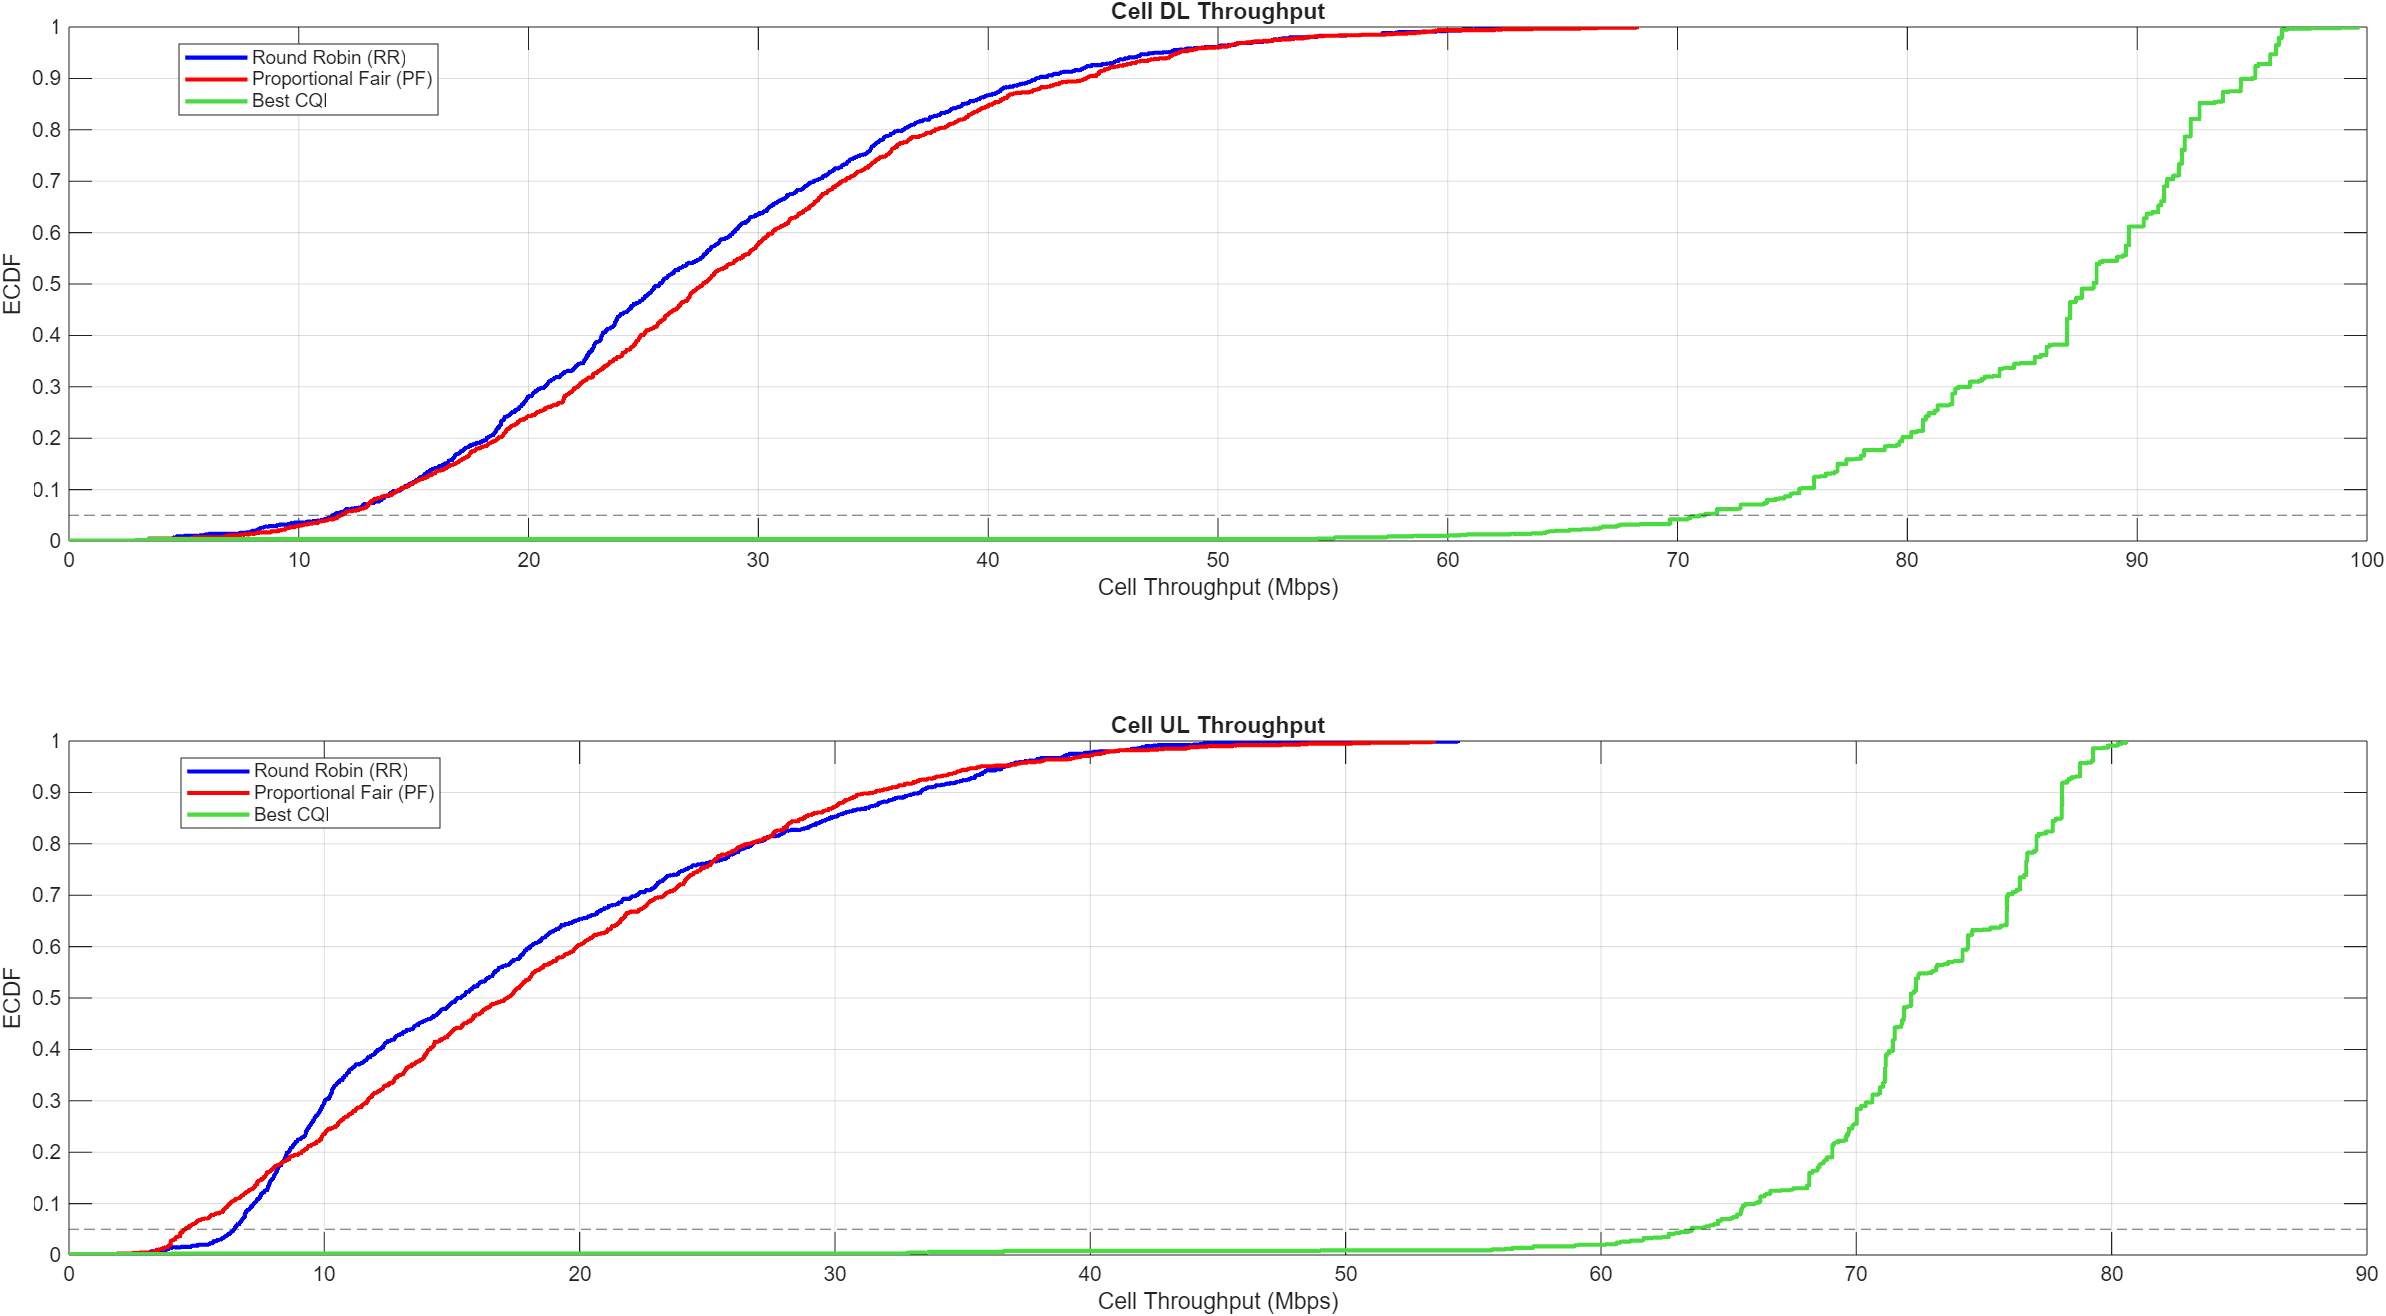

## Supporting Functions

The example uses these helpers:

- [helperNRMetricsVisualizer.m](matlab:openExample('5g/NRFDDSchedulingPerformanceEvaluationExample','supportingFile','helperNRMetricsVisualizer')): Implements metrics visualization functionality

- [helperNRSchedulingLogger.m](matlab:openExample('5g/NRFDDSchedulingPerformanceEvaluationExample','supportingFile','helperNRSchedulingLogger')): Implements scheduling information logging functionality

- [helperNRRLCLogger.m](matlab:openExample('5g/NRFDDSchedulingPerformanceEvaluationExample','supportingFile','helperNRRLCLogger')): Implements RLC packet transmission and reception information logging functionality

- [helperNRGridVisualizer.m](matlab:openExample('5g/NRFDDSchedulingPerformanceEvaluationExample','supportingFile','helperNRGridVisualizer')): Implements channel quality and resource grid visualization functionality

- [h38901Channel.m](matlab:open('./h38901Channel.m')): Implements the 3GPP TR 38.901 channel model

- [helperNRMACPacketCapture.m](matlab:open('./helperNRMACPacketCapture.m')): Implements the NR MAC packets capturing functionality

*Copyright 2019-2024 The MathWorks, Inc.*